# NNSAMPLE Sample Training Session

A feed-forward network is trained to perform a nonlinear regression between spectral components and cholesterol levels. The final network is analyzed to investigate overall performance.

% Copyright 1994-2015 Martin T. Hagan and Howard B. Demuth

figure(gcf);
clf;
echo on;
clc;

Load inputs X, a 21x264 matrix defining twenty-one spectral measurements of 264 blood samples, and targets T, a 3x264 matrix of levels of three kinds of cholesterol for each blood sample.

[x,t] = cho_dataset;

## 查看创建浅层神经网络对象的代码

Create a feedforward network with 5 hidden neurons. We add an input processing step that performs principle component analysis on the input data and removes those components which account for less than 0.1% of the variation.

% 创建浅层神经网络对象
% 相关文档：
% 1. https://ww2.mathworks.cn/help/releases/R2025b/deeplearning/ref/feedforwardnet.html
% 2. https://ww2.mathworks.cn/help/releases/R2025b/deeplearning/ref/network.html
% 相关的Matlab库代码：
% /Applications/MATLAB_R2025b.app/toolbox/nnet/nnshallow/nncore/@network/network.m
% 创建network对象的方法:
% /Applications/MATLAB_R2025b.app/toolbox/nnet/nnshallow/nncore/nnnetwork/feedforwardnet.m
% dbtype /Applications/MATLAB_R2025b.app/toolbox/nnet/nnshallow/nncore/nnnetwork/feedforwardnet.m 101:149
fprintf('创建浅层神经网络对象的函数')

创建浅层神经网络对象的函数

dbtype /Applications/MATLAB_R2025b.app/toolbox/nnet/nnshallow/nncore/nnnetwork/feedforwardnet.m 101:149


101   
102   function net = create_network(param)
103   
104     % Layers
105     net = network;
106     Nl = length(param.hiddenSizes)+1;
107     net.numLayers = Nl;
108     net.biasConnect = true(Nl,1);
109     [j,i] = meshgrid(1:Nl,1:Nl);
110     net.layerConnect = (j == (i-1));
111     for i=1:Nl
112       if i == Nl
113         net.layers{i}.name = 'Output';
114       else
115         if (Nl == 2)
116           net.layers{i}.name = 'Hidden';
117         else
118           net.layers{i}.name = ['Hidden ' num2str(i)];
119         end
120         net.layers{i}.size = param.hiddenSizes(i);
121         net.layers{i}.transferFcn = 'tansig';
122       end
123       net.layers{i}.initFcn = 'initnw';
124     end
125     
126     % Inputs
127     net.numInputs = 1;
128     net.inputConnect(1,1) = true;
129     net.inputs{1}.processFcns = {'removeconstantrows','mapminmax'};
130     
131     % Outputs
132     net.outputConnect(Nl) = true;
133     net.outputs{Nl}.processFcns = {'removeconstan

net = feedforwardnet(5);
net.inputs{1}.processFcns = [{'processpca'} net.inputs{1}.processFcns];
% net.inputs{1}.processParams{1}.max_frac = 0.001;
% max_frac字段名称非法，应该使用maxfrac
net.inputs{1}.processParams{1}.maxfrac = 0.001;

Train the network using early stopping.

[net,tr] = train(net,x,t);

Plot the training, validation and test errors.

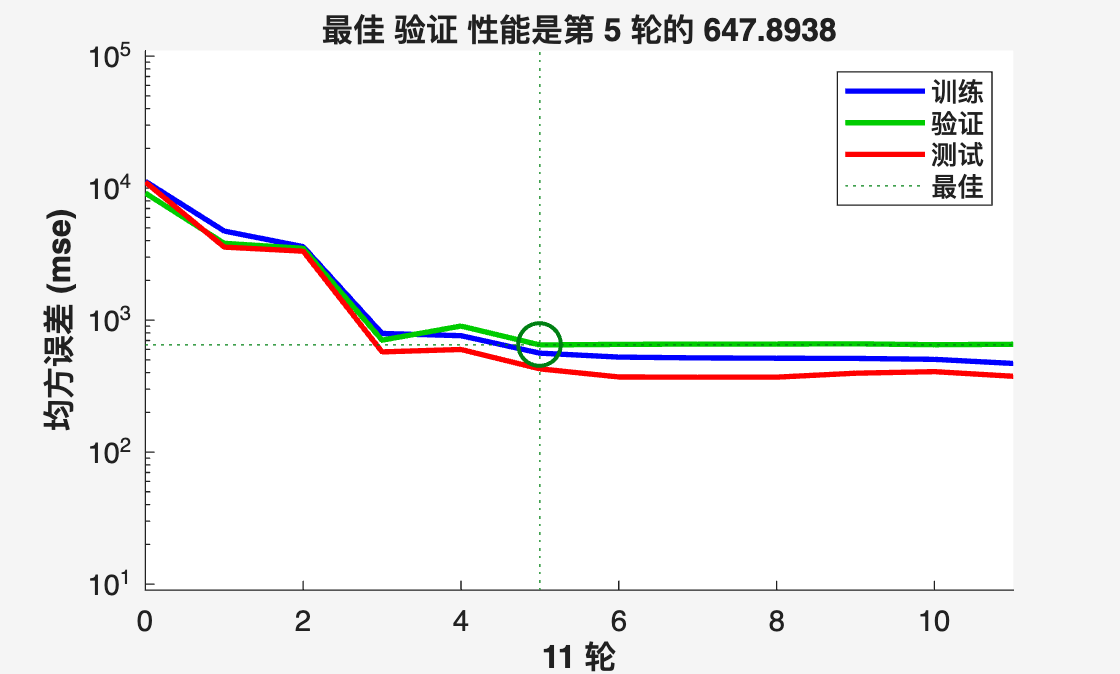

plotperform(tr);

Simulate the trained network.

y = net(x);

Plot regression analysis for output element 1.

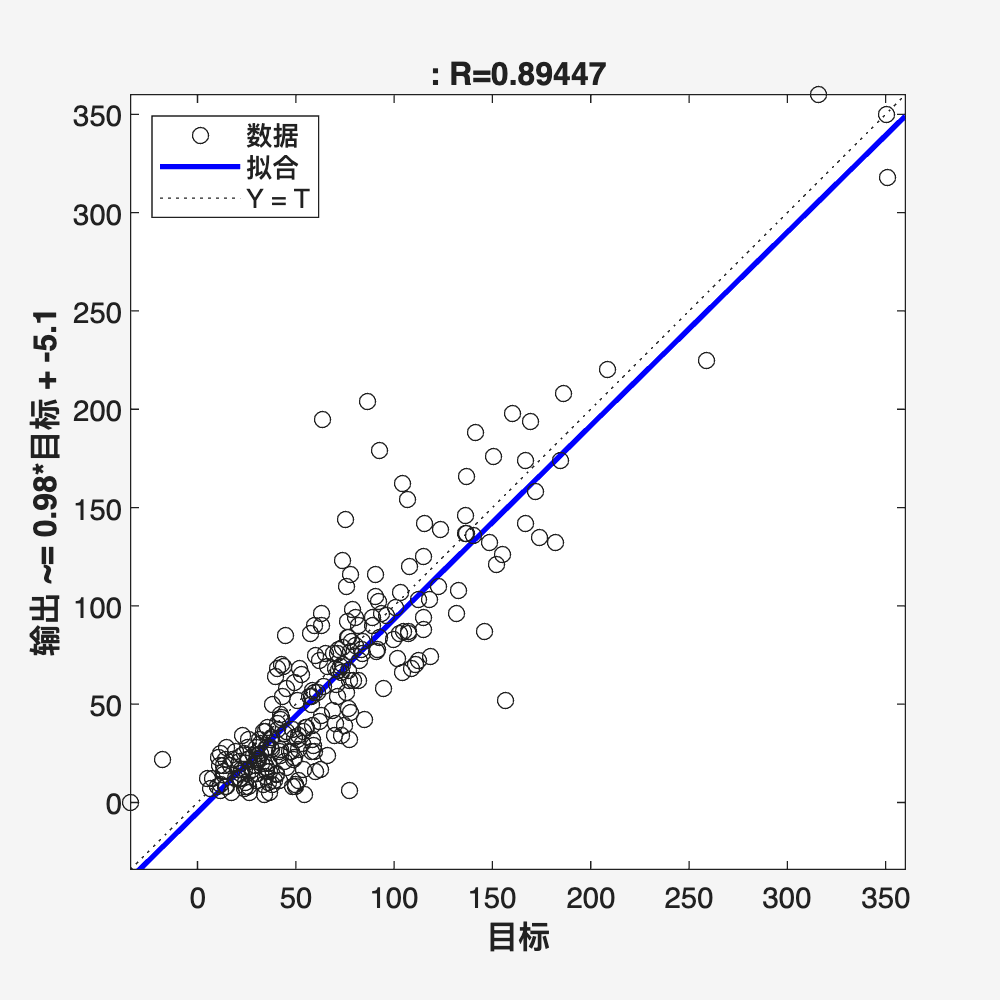

i = 1;
plotregression(y(i,:),t(i,:));

[r(i),m(i),b(i)] = regression(y(i,:),t(i,:));

Plot regression analysis for output element 2.

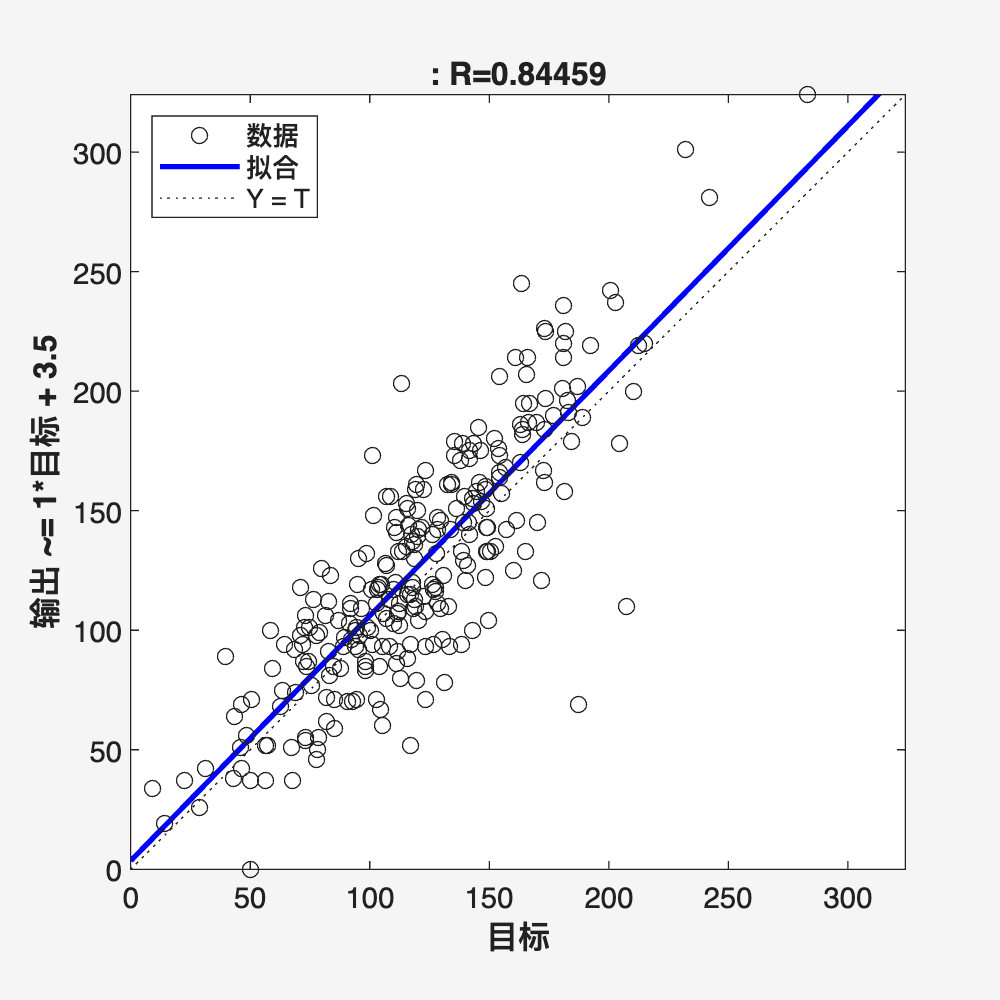

i = 2;
plotregression(y(i,:),t(i,:));

[r(i),m(i),b(i)] = regression(y(i,:),t(i,:));

Plot regression analysis for output element 3.

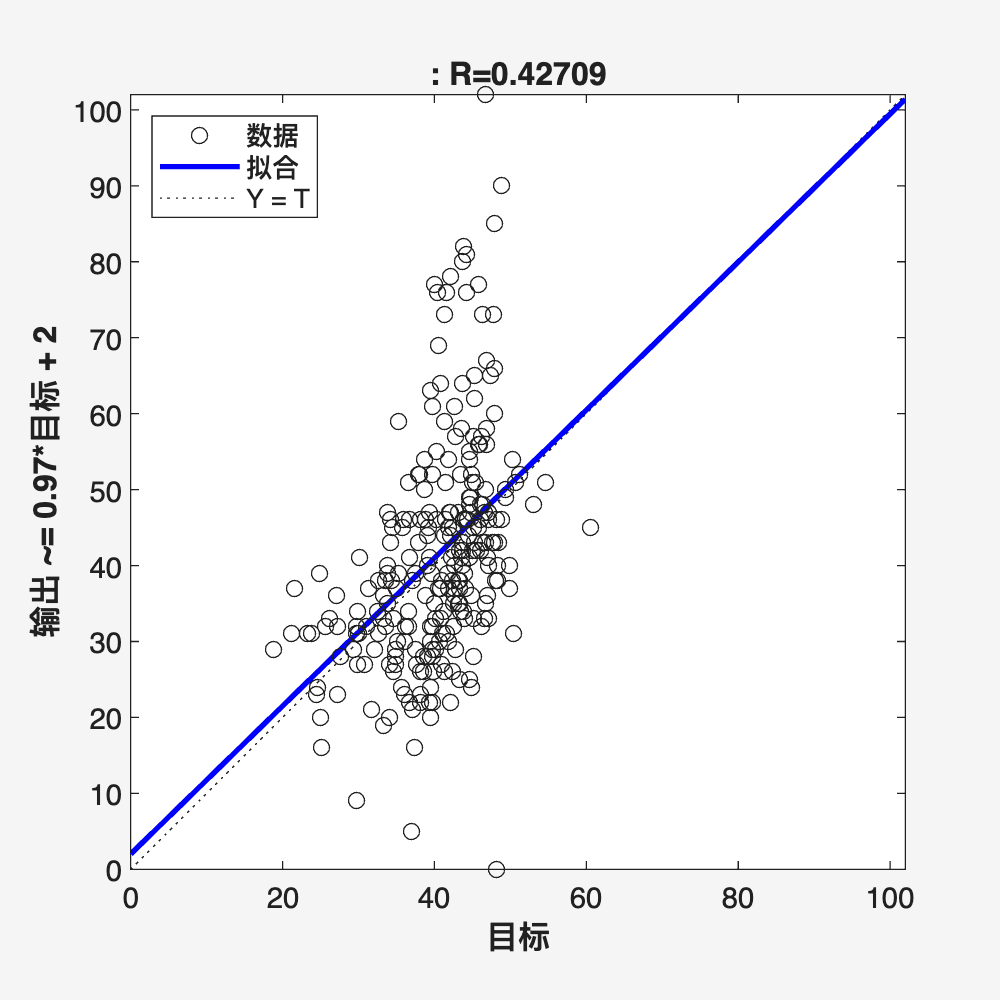

i = 3;
plotregression(y(i,:),t(i,:));

[r(i),m(i),b(i)] = regression(y(i,:),t(i,:));